clear;
close all;

# `Leitura dos dados`

inputData = load('InputData.mat');
outputData = load('OutputData.mat');

X = inputData.InputData';
y = outputData.OutputData;

# `Extração de Atributos`

signal = X';

% Extrair atributos do domínio do tempo
[features_time, attributes_time] = extract_time_features(signal);
features_time = fillmissing(normalize(features_time'), 'constant', 0);
features_time = array2table(features_time, 'VariableNames', attributes_time);

% Extrair atributos do domínio da frequência (Transformada de Fourier)
[features_freq, attributes_freq] = extract_freq_features(signal);
features_freq = fillmissing(normalize(features_freq'), 'constant', 0);
features_freq = array2table(features_freq, 'VariableNames', attributes_freq);

% Extrair atributos do domínio da fase (Transformada de Fourier)
[features_angle, attributes_angle] = extract_phase_features(signal);
features_angle = fillmissing(normalize(features_angle'), 'constant', 0);
features_angle = array2table(features_angle, 'VariableNames', attributes_angle);

% Extrair atributos utilizando Transformada discreta de cosseno   
[features_dct, attributes_dct] = extract_dct_features(signal);
features_dct = fillmissing(normalize(features_dct'), 'constant', 0);
features_dct = array2table(features_dct, 'VariableNames', attributes_dct);

X_features = horzcat(features_time, features_freq, features_dct, features_angle);

# `Aplicanção K-fold`

`Foram utilizados 17 atributos, com o melhor caso atingindo 100% de acurácia na base de dados, algo que é observado regularmente. A seguir, apresenta-se o plot 1D de cada atributo, demonstrando a distribuição das classes em relação a cada um deles.`

[best_k, accuracy] = K_fold(X_features, y);
fprintf('A melhor acurácia foi de %.2f%% com k=%d\n', accuracy*100, best_k);

A melhor acurácia foi de 100.00% com k=1


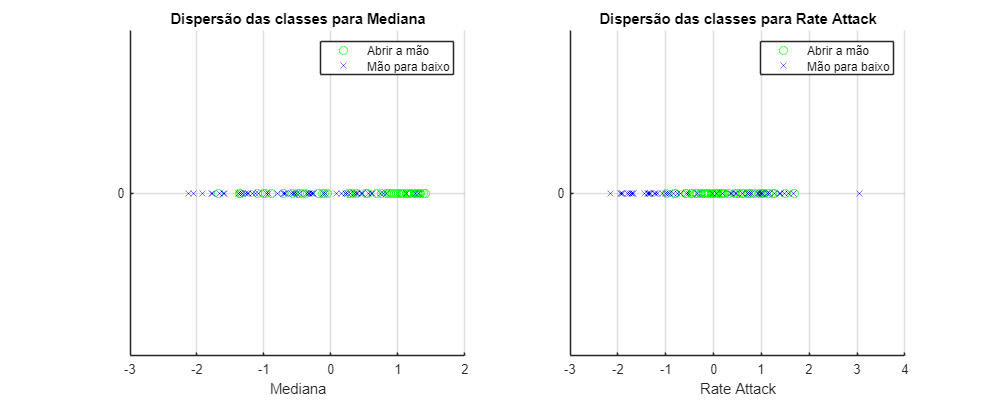

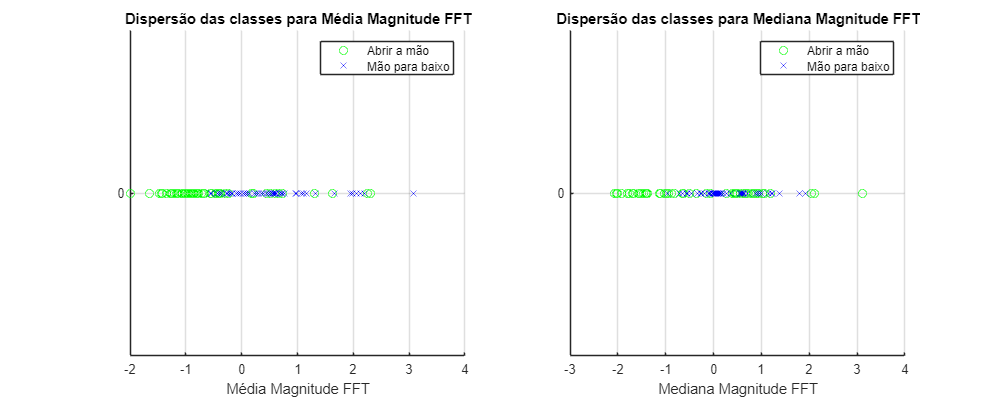

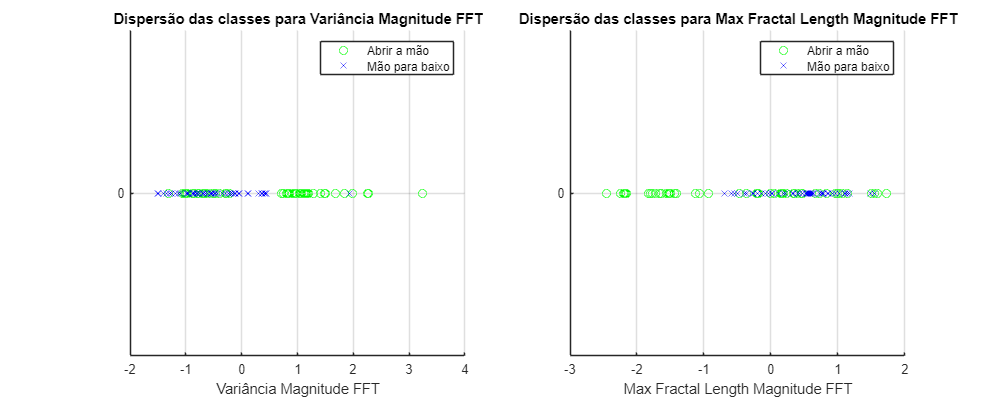

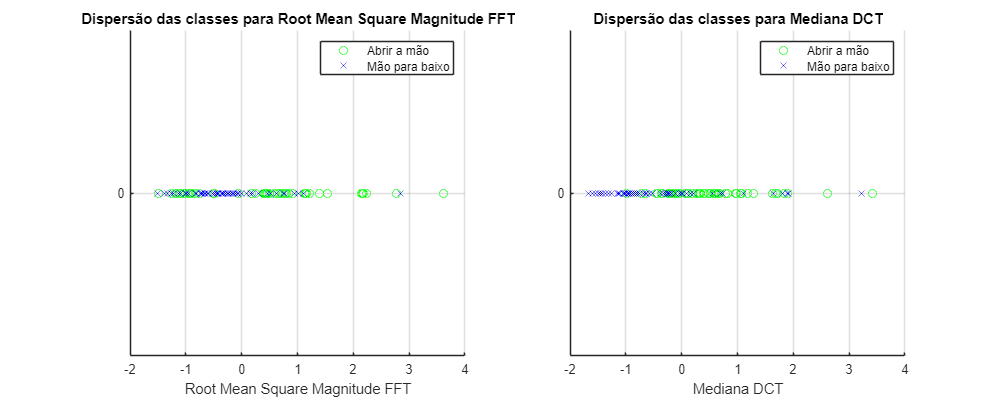

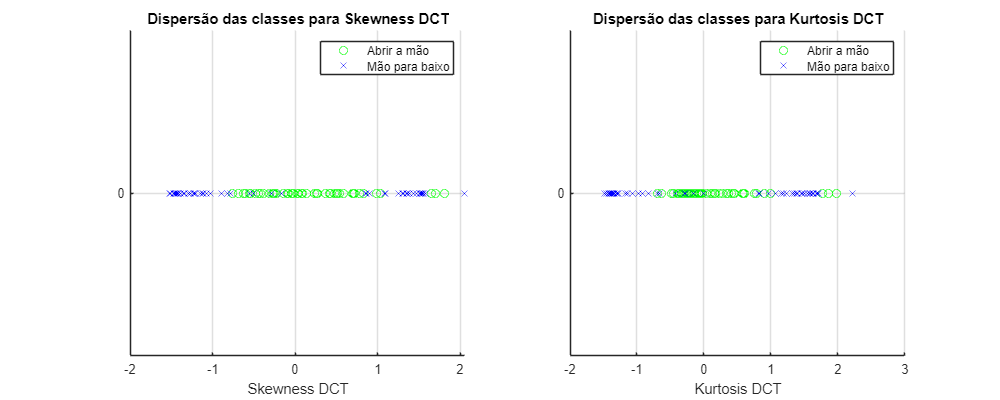

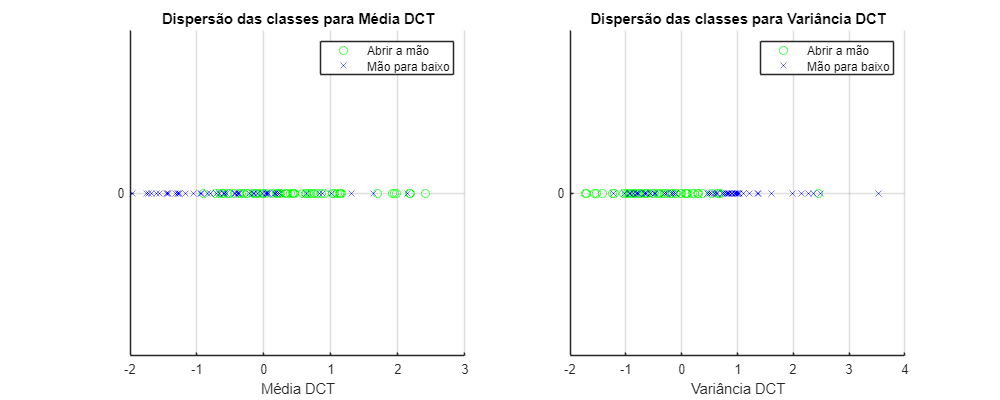

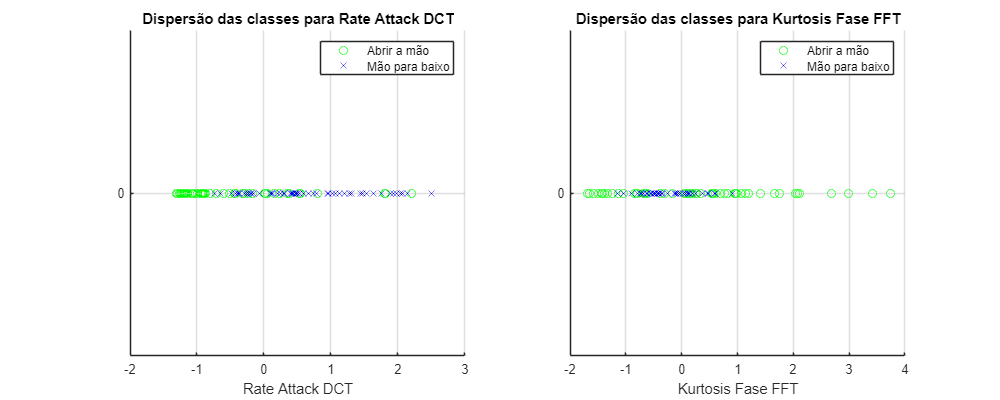

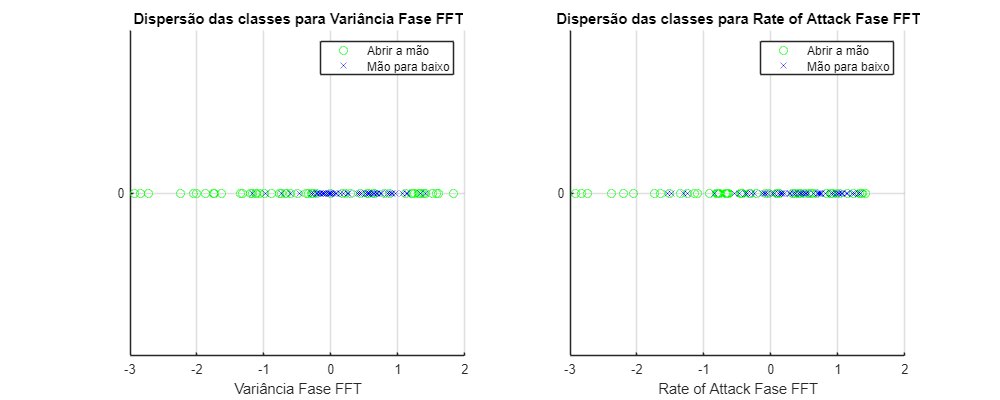

plotClassScatter(X_features, y);

`É possível configurar uma base com apenas 5 atributos, resultando em uma queda de menos de 3% na acurácia em comparação com a base anterior que possuía 17 atributos, atingindo, no melhor caso, 99,17% de acurácia, o que ocorre com certa frequência. Isso levanta a questão da relação entre ``quantidade de atributos vs acurácia``.`

X_features_reduct = horzcat(features_time(:,2), features_freq(:,4), features_dct(:,[2,6]), features_angle(:,1));
X_features_reduct

X_features_reduct = 120×5 table
    Rate Attack    Max Fractal Length Magnitude FFT    Skewness DCT    Rate Attack DCT    Kurtosis Fase FFT
    ___________    ________________________________    ____________    _______________    _________________

      -0.57546                  -1.0656                  -0.26795          -1.0226             0.60569     
      0.052218                  -1.4043                  -0.30726          -1.2668            0.058375     
        1.2271                   -1.555                  -0.24958          -1.1826            0.068655     
       0.17288                  -2.1596                 -0.090419          -1.2946             0.69534     
      -0.32672                  -1.4474                 -0.031632          -1.1727             0.54276     
        0.0374                  -1.8256  

[best_k, accuracy] = K_fold(X_features_reduct, y);
fprintf('A melhor acurácia foi de %.2f%% com k=%d\n', accuracy*100, best_k);

A melhor acurácia foi de 99.17% com k=1


# `Função Utilizadas`

- `Função responsável pelo algoritmo KNN`

function prediction = kNN(X, y, new_X, k)
    while k > 0
        
        distances = table2array(sqrt(sum((X - new_X).^2,2))); % Calcular a distância euclidiana
        [~, sorted_indices] = sort(distances);
        nearest_neighbors = y(sorted_indices(1:k));
        
        % Verificação de empate entre as classes
        [unique_elements, ~, idx] = unique(nearest_neighbors);
        if length(unique_elements) > 1
            counts = histcounts(idx, 1:(numel(unique_elements)+1));
            if all(counts == counts(1))
                k = k - 1; % Reduzir k e repetir a operação
            else
                break;
            end
        else
            break;
        end
    end
    prediction = mode(nearest_neighbors);
end

- `Função de aplicação do K-Fold`

function [best_k, accuracy] = K_fold(X_features, y, num_folds, k_values)
   
    % Define valores padrão para num_folds e k_values se não forem fornecidos
    if nargin < 3
        num_folds = 10; % Quantidade de folds padrão
    end
    if nargin < 4
        k_values = 1:5; % Valores de K neighbors padrão
    end

    % Gerar índices aleatórios para os dados
    random_indexs = randperm(height(X_features));
    step_test = ceil(height(X_features) / num_folds);

    % Inicializar matriz para armazenar a média das acurácias de cada k
    k_acuracies = zeros(length(k_values), 1);

    for id_k = 1:length(k_values)
        k = k_values(id_k);
        accuracies = zeros(num_folds, 1); % Armazena as acurácias de k para todos os folds
        for i = 1:num_folds   
            % Dividindo em treino e teste
            train_idx = random_indexs;
            train_idx(i * step_test - step_test + 1: i * step_test) = [];
            test_idx = random_indexs(i * step_test - step_test + 1: i * step_test);

            X_train = X_features(train_idx, :);
            y_train = y(train_idx, :);
            X_test = X_features(test_idx, :);
            y_test = y(test_idx, :);

            % Aplicando o KNN
            num_correct = 0;
            for j = 1:length(y_test)
                prediction = kNN(X_train, y_train, X_test(j, :), k);
                if prediction == y_test(j)
                    num_correct = num_correct + 1;
                end
            end
            accuracies(i) = num_correct / length(y_test);
        end
        k_acuracies(id_k) = mean(accuracies);
    end

    % Encontrar a melhor acurácia e o melhor valor de K
    [accuracy, idx_k] = max(k_acuracies);
    best_k = k_values(idx_k);
end

- `Funções para extração dos atributos da base de dados:`

function [features_time, attributes_time] = extract_time_features(signal)
    attributes_time = {'Mediana', 'Rate Attack'};
    
    features_time = [];
    features_time = [features_time; median(signal)]; % Mediana
    features_time = [features_time; max(diff(signal) / length(signal))]; % Rate Attack

end

function [features_freq, attributes_freq] = extract_freq_features(signal)
    attributes_freq = {'Média Magnitude FFT', 'Mediana Magnitude FFT', ...
        'Variância Magnitude FFT','Max Fractal Length Magnitude FFT', 'Root Mean Square Magnitude FFT'};
    
    Y = fftshift(fft(signal));
    mag_fft = abs(Y);
    
    features_freq = [];
    features_freq = [features_freq; mean(mag_fft)]; % Média
    features_freq = [features_freq; median(mag_fft)]; % Mediana
    features_freq = [features_freq; var(mag_fft)]; % Variância
    features_freq = [features_freq; log10(sqrt(sum(diff(mag_fft).^2)))]; % Max Fractal Length
    features_freq = [features_freq; rms(mag_fft)]; % Root Mean Square
end

function [features_angle, attributes_angle] = extract_phase_features(signal)
    attributes_angle = {'Kurtosis Fase FFT', 'Variância Fase FFT',...
        'Rate of Attack Fase FFT', 'Rate of Decay Fase FFT'};
    
    Y = fftshift(fft(signal));
    phase_fft = angle(Y);
    
    features_angle = [];
    features_angle = [features_angle; kurtosis(phase_fft)]; % Curtose
    features_angle = [features_angle; var(phase_fft)]; % Variância
    features_angle = [features_angle; max(diff(phase_fft) / length(phase_fft))]; % Rate of Attack ANGLE
    features_angle = [features_angle; rate_of_decay(phase_fft)]; % Rate of Decay ANGLE
end

function [features_dct, attributes_dct] = extract_dct_features(signal)
    attributes_dct = {'Mediana DCT', 'Skewness DCT', 'Kurtosis DCT', 'Média DCT',...
        'Variância DCT', 'Rate Attack DCT'};
    
    mag_dct = abs(dct(signal));
    
    features_dct = [];
    features_dct = [features_dct; median(mag_dct)]; % Mediana
    features_dct = [features_dct; skewness(mag_dct)]; % Skewness
    features_dct = [features_dct; kurtosis(mag_dct)]; % Kurtosis
    features_dct = [features_dct; mean(mag_dct)]; % Média
    features_dct = [features_dct; var(mag_dct)]; % Variância
    features_dct = [features_dct; max(diff(mag_dct) / length(mag_dct))]; % Rate Attack

end

function mind = rate_of_decay(InputData)
    n = length(InputData);
    dif = zeros(n-1, size(InputData, 2));
    for i = 1:n-1
        dif(i,:) = (InputData(i,:) - InputData(i+1,:)) / n;
    end
    mind = min(dif);
end

- `Função para o plot do gráficos`

function plotClassScatter(X_features, y)
    % Obtém os nomes dos atributos
    attribute_names = X_features.Properties.VariableNames;
    num_attributes = length(attribute_names);
    
    % Determinar o tamanho da grade de subplots
    num_rows = 1;
    num_cols = 2;

    % Determina o número de subplots por figura
    num_subplots = num_rows * num_cols;

    % Plotar a dispersão das classes para todos os atributos
    for i = 1:ceil(num_attributes / num_subplots)
        figure('Position', [100, 100, 1000, 400]);
        for j = 1:num_subplots
            idx = (i - 1) * num_subplots + j;
            if idx > num_attributes
                break;
            end
            subplot(num_rows, num_cols, j);
            hold on; grid on;

            class_neg1 = y == -1;
            class_pos1 = y == 1;

            scatter(X_features{class_neg1, idx}, zeros(sum(class_neg1), 1), 'green', 'o'); 
            scatter(X_features{class_pos1, idx}, zeros(sum(class_pos1), 1), 'blue', 'x'); 
            xlabel(attribute_names{idx});
            ylabel('');
            title(['Dispersão das classes para ', attribute_names{idx}]);

            set(gca, 'ytick', 0);
            ylim([-0.5, 0.5]);

            legend('Abrir a mão', 'Mão para baixo', 'Location', 'northeast');
            hold off;
        end
    end
end